# Indoor Channel Data

For the lab in this unit, we will use ray tracing data from an indoor environment.  This ray tracing data was produced by Mingsheng Yin as part of larger project on localization.  If you are interested, he has mapped about 100 rooms from a widely-used robotics dataset.  Ask him for the data if you are interested.  He will be uploading it shortly.  

In this demo, you will learn to:

- Load the data and inspect the data structure

- Visualize simple characteristics of the data graphically

## Loading the Data

The data can be loaded as follows.  The mat file is in the github directory

load roomPathData.mat

When you load the data you should see a structure, `pathData`.  In the data, there was a single TX and a large number of RX locations.  The configuration of the file is described in the following fields:

- `pathData.fc` :  The carrier frequency in Hz

- `pathData.txPos` :  The `(x,y)` position of the TX. 

- `pathData.posStep`:  The `(x,y)` grid spacing on which the RX locations were taken

The remaining fields are arrays with one row per RX location.  Some key fields are:

- `pathData.rxPos(i,:) : `The `(x,y)` position of the RX location `i`

- `pathData.npaths(i) : `The number of valid paths for RX location `i` .

- `pathData.linkState(i): 0=Outage = `No paths to this link, 1=LOS path, 2 = NLOS paths only.

For other fields, there is one column per path.  For position `i,` the paths will run from `j=1,...,npaths(i):  `

- `pathData.pl(i,j) : `The path loss on path `j` for RX location `i` .

- `pathData.aoaAz(i,j), aoaEl(i,j) : `The azimuth and elevation angle of arrival of path `j` for RX location `i` .

- `pathData.aodAz(i,j), aodEl(i,j) : `The azimuth and elevation angle of departure of  path `j` for RX location `i` .

As an example, we can print the total area:

minPos = min(pathData.rxPos);
maxPos = max(pathData.rxPos);
posArea = maxPos - minPos;
dsep = pathData.posStep

dsep =     0.1500    0.1500


fprintf('The area is %7.2f m x %7.2f m\n', posArea(1), posArea(2));

The area is   14.25 m x   16.65 m


We can also print the number of RX locations and fraction in each link state.

nrxPos = size(pathData.rxPos, 1);


fprintf(1,'Number of RX locations = %d\n', nrxPos);

Number of RX locations = 5071



for i = 1:length(pathData.linkStateLabel)
    p = mean(pathData.linkState == i-1);
    fprintf(1,'Fraction %10s = %7.5f\n', pathData.linkStateLabel{i}, p);
end

Fraction     Outage = 0.04969
Fraction        LOS = 0.67127
Fraction       NLOS = 0.27904


## Visualizing the LOS state

To help visualize the data, I have created a simple class, `DataMapper`.  You create the object with the positions on which the values will be mapped.  In this case, the positions are `rxPos`.   You also provide the grid spacing.

rxPos = pathData.rxPos;
mapper = DataMapper(rxPos, pathData.posStep);

Once you have created the `mapper` object, you can give it any values to plot. For example, suppose we plot the link state. The link states have values 0,1,2.  We will add a value of `noVal = 3` for positions on which data is not provided.

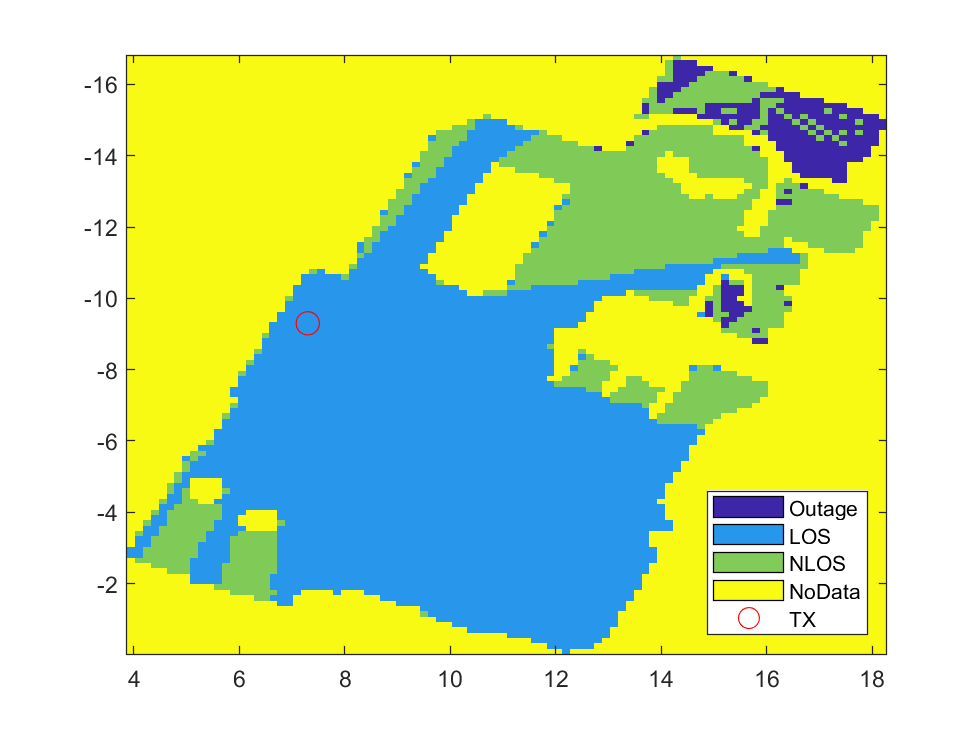


clf;
noDataValue = 3;  % Use this value for positions with no data

% Legend labels
legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

% Call the plot.  Use `plotHold=true` to hold the plot so we can overlay
% other items
mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);

% Overlay the TX position
txPos = pathData.txPos;
plot(txPos(1), txPos(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'TX');
hold off;

% Display the legend
legend('Location', 'SouthEast');

## Plotting the RX power and SNR

As another plotting example, we can compute the total RX power by  summing the power from each path.  This is the power that would be received with omni-directional TX and RX.

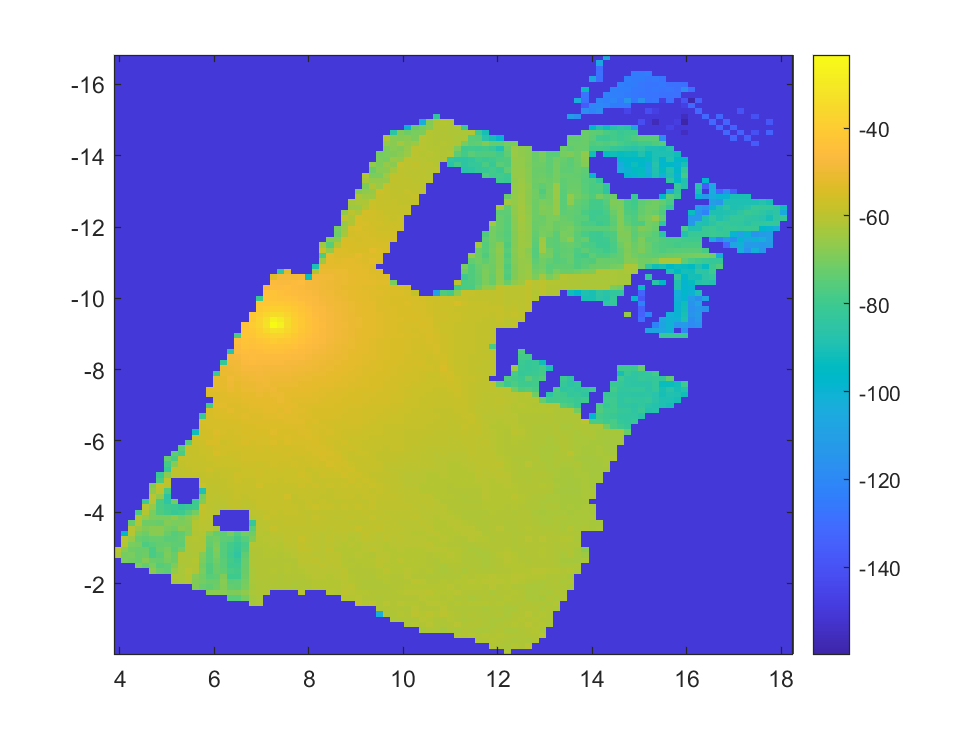


txPow = 15;  % TX power in dBm

% Get the path loss data
plos = pathData.pl;
nlinks = size(plos,1);

% Initialize locations to a minimum power
rxPowMin = -150;
rxPow = repmat(rxPowMin, nlinks,1);

% Loop over the locations and compute the RX power
for i = 1:nlinks
    k = pathData.npaths(i); 
    if k >  0
        rxPow(i) = txPow + pow2db(sum(db2pow(-plos(i,1:k))));
    end
end

% Plot the results
mapper.plot(rxPow, 'noDataValue', rxPowMin);
colorbar();

We could also plot the SNR with omni antennas.

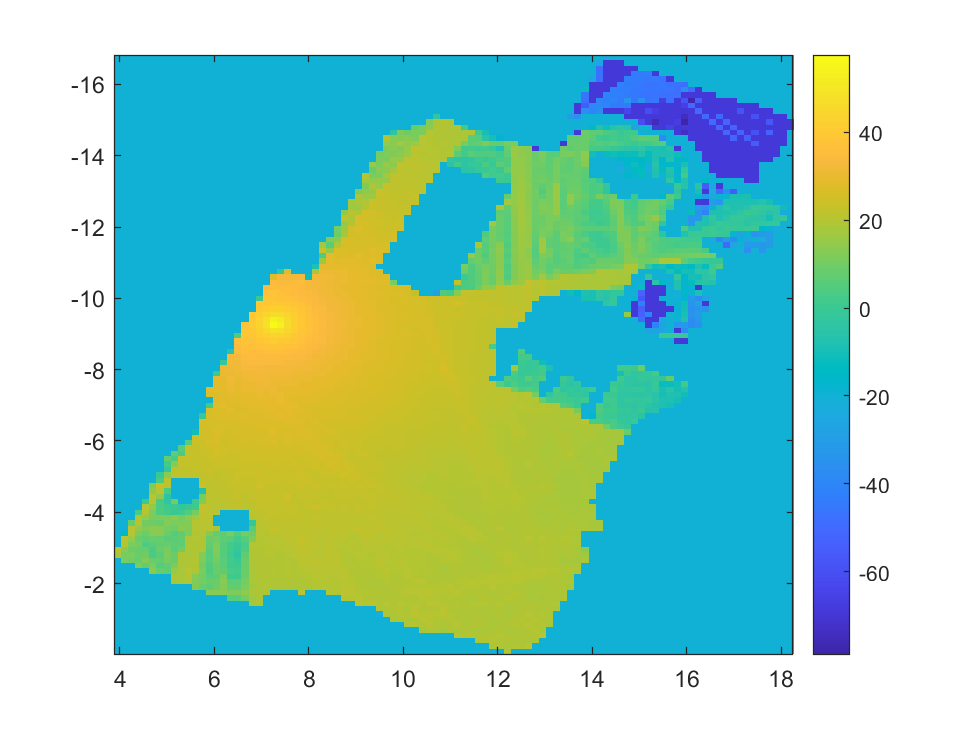

nf = 7;      % Noise figure
bw = 400e6;  % Bandwidth
Ekt = -174;  % Theremal noise

% SNR
snr = rxPow - nf - Ekt - 10*log10(bw);

% Plot the results
snrMin = -20;
mapper.plot(snr, 'noDataValue', snrMin);
colorbar();